
%{
ES115- Class-Project
Author: Matthew Chietro
Version: 1.0
Date: 2026-04-14
Purpose:
    - To compare two solar billing plans using linear and piecewise models.
    - To determine cost differences and break-even usage levels.
    - To visualize and tabulate billing data for analysis.

Input:
    - Energy usage vector with user input

Output:
    - Plot comparing Plan A and Plan B
    - Break-even usage value(s)
    - Table of usage vs cost for both plans
    - Recommendation for plan selection

Engineering Algorithms:
    - Define usage vector
    - Compute Plan A using linear equation
    - Compute Plan B using piecewise logic
    - Plot both plans and mark 400 kWh breakpoint
    - Find intersection point where costs are equal
    - Generate table of values
    - Display results using fprintf

MATLAB tools/functions:
    - function, input,
    - for loop, if/else
    - plot, text, xlabel, ylabel, legend
    - fprintf
%}

% Define energy usage vector from 0 to 800 in steps of 25 kWh
[a1,a2,a3] = GetUserInput ()  % all function to get user input 

a1 = 8

a2 = 9

a3 = 800

x = a1: a2: a3  % Values for x created from user input  

x =      8    17    26    35    44    53    62    71    80    89    98   107   116   125   134   143   152   161   170   179   188   197   206   215   224   233   242   251   260   269   278   287   296   305   314   323   332   341   350   359   368   377   386   395   404   413   422   431   440   449


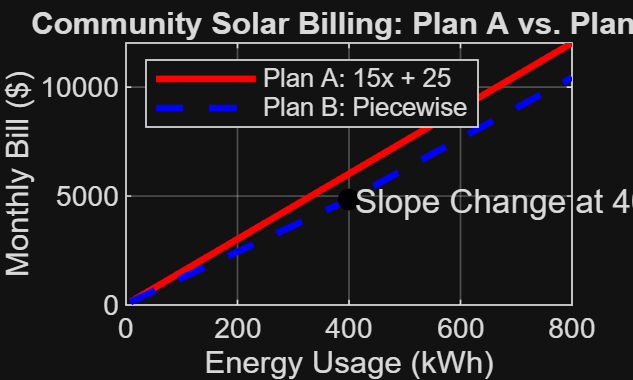

% Define billing for Plan A
BA = 15*x + 25;
% Define billing for Plan B
BB = zeros(size(x));
% Build piecewise billing for Plan B
for i = 1:length(x)
    if x(i) <= 400
        % Lower-rate segment up to 400 kWh
        BB(i) = 12*x(i) + 40;
    else
        % Higher-rate segment above 400 kWh (offset adjusted)
        % Simplified: 14x + (40 - 800) -> 14x - 760
        BB(i) = 14*x(i) - 760;
    end
end
% Plot BA and BB vs x with styling; keep figure open for further edits
figure;
plot(x, BA, 'r-', 'LineWidth', 2); hold on;
plot(x, BB, 'b--', 'LineWidth', 2);
grid on;
% Define a break point in data/axes at x=400 and corresponding y value
x_break = 400;
y_break = 12*400 + 40;
% Mark and label the slope change at the breakpoint
plot(x_break, y_break, 'ko', 'MarkerFaceColor', 'k');
% Annotate a slope-change marker near the break point
text(x_break + 10, y_break - 100, 'Slope Change at 400 kWh', 'FontSize', 10);
% Label x-axis as energy usage in kWh
xlabel('Energy Usage (kWh)');
% Label y-axis as monthly bill in dollars
ylabel('Monthly Bill ($)');
% Title describing the comparison being plotted
title('Community Solar Billing: Plan A vs. Plan B');
% Legend describing the two plotted plans, placed northwest
legend('Plan A: 15x + 25', 'Plan B: Piecewise', 'Location', 'northwest');



%This function returns a 1 by 3 matrix
function [start, incr, stop] = GetUserInput () % Function requires no input arguments 
    start = input('Enter the starting usage ');
    if start < 0 
        start = 0;
    end
    incr = input('Enter the increment ');
    if incr <  0 
        incr = 25;
    end
    stop = input('Enter the End value ');
     if stop < start || stop < 0 || stop < 800
        stop = 800;
     end 
end